**    SPECTRUM ANALYZER FOR 1 WINDOW**

[x1,fs] = audioread('Spectrum Analyzer_MATLAB/music.wav'); 
if size(x1,2) > 1 
    x1 = x1(:,1); % mono 
end

N = length(x1)

N = 11687936

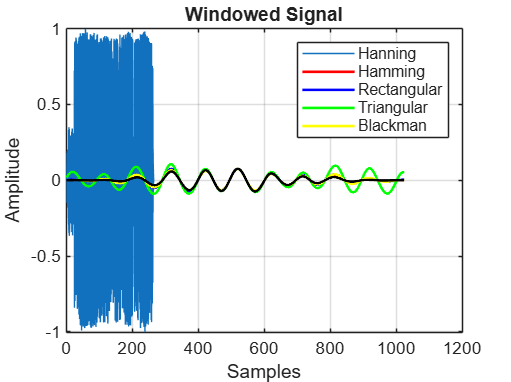

t = (0:length(x1)-1)/fs;
figure(1) 
plot(t,x1) 
xlabel('Time (seconds)') 
ylabel('Amplitude') 
title('Time-domain representation of the song') 
grid on

%Initialize
L = 1024; %Window length
start = 200000;  % pick a later sample (e.g. ~4.5 sec into audio if fs=44100)

% Windows
w1 = hann(L);
w2 = hamming(L);
w3 = rectwin(L);
w4 = triang(L);
w5 = blackman(L);
Windowedsignal1 = x1(start:start+L-1).*w1;
Windowedsignal2 = x1(start:start+L-1).*w2;
Windowedsignal3 = x1(start:start+L-1).*w3;
Windowedsignal4 = x1(start:start+L-1).*w4;
Windowedsignal5 = x1(start:start+L-1).*w5;

figure(2)
hold on
plot(Windowedsignal1, 'r', 'LineWidth', 1.5);
plot(Windowedsignal2, 'b', 'LineWidth', 1.5);
plot(Windowedsignal3, 'g', 'LineWidth', 1.5);
plot(Windowedsignal4, 'y', 'LineWidth', 1.5);
plot(Windowedsignal5, 'k', 'LineWidth', 1.5);
hold off

legend('Hanning','Hamming','Rectangular','Triangular','Blackman')
xlabel('Samples') 
ylabel('Amplitude') 
title('Windowed Signal') 
grid on

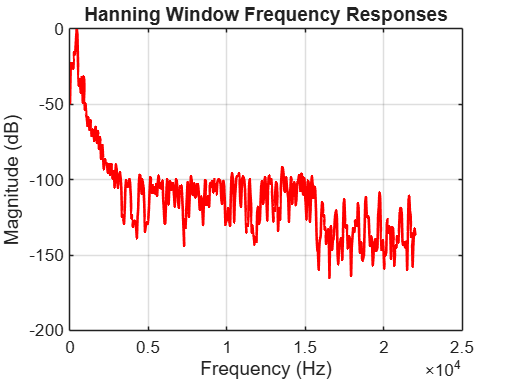



% Compute the FFT of the windowed signal
W1 = fft(Windowedsignal1, L);
% Frequency axis (only first half)
f = (0:L/2-1)*(fs/L);

% Normalize EACH window's FFT to its own max
M1 = 20*log10(abs(W1(1:L/2))/max(abs(W1)) + eps);

% Plot
figure(3)
plot(f, M1,'LineWidth',1.5,'Color','r');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Hanning Window Frequency Responses');  
grid on;

**SPECTRUM ANALYZER FOR COMPLETE AUDIO**

[x1,fs] = audioread('Spectrum Analyzer_MATLAB/music.wav'); 

if size(x1,2) > 1 
    x1 = x1(:,1); % mono 
end

%initialize
N = length(x1);
L = 1024; 
hop = L/2;   % 50% overlap
w = hann(L);

% Number of frames
NFrames = floor((N-L)/hop)  %Approximates total number of windows

NFrames = 22826

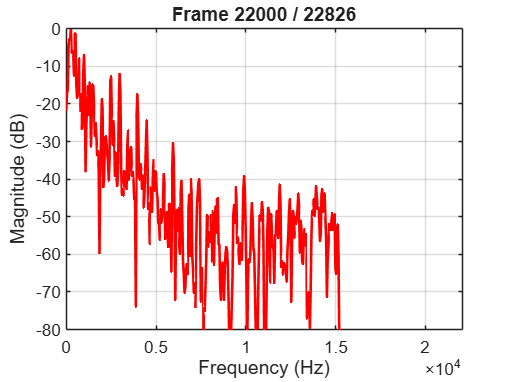

M_all = zeros(L/2, NFrames);
%Looping
figure(4)
for k = 1:NFrames
    idx = (1:L) + (k-1)*hop;
    frame = x1(idx).*w;
    W3 = fft(frame,L);
    M = 20*log10(abs(W3(1:L/2))/max(abs(W3)) + eps);
    M_all(:,k) = 20*log10(abs(W3(1:L/2)) + eps);  % store absolute dB
    
    % Only update the plot every 10 frames
    if mod(k,1000) == 0
        plot(f,M,'r','LineWidth',1.5)
        xlabel('Frequency (Hz)')
        ylabel('Magnitude (dB)')
        title(sprintf('Frame %d / %d', k, NFrames))
        axis([0 fs/2 -80 0])
        grid on
        drawnow
    end
end


figure(5)
imagesc((0:NFrames-1)*hop/fs, f, M_all);   % plot as image
axis xy; 
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of Complete Audio using looping');

**SPECTROGRAM**

%Spectrogram in-built
figure(6)
[s,f,t] = spectrogram(x1, w, L-hop, L, fs);   % compute spectrogram
S_dB = 20*log10(abs(s) + eps);     % convert to dB
% plot as image
imagesc(t,f,S_dB-60);   
axis xy; 
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of Complete Audio using in-built function');

**SPECTRAL ANALYSIS ON LIVE AUDIO**

inputID = 1;                
fs = 16000;                 
recorder = audiorecorder(fs, 16, 1, inputID);
record(recorder);  % starts recording
pause(5);          % wait
stop(recorder);    % stop recording
data = getaudiodata(recorder);
% Play the recorded audio
sound(data, fs);

t = (0:length(data)-1)/fs;
figure(7) 
plot(t,data) 
xlabel('Time (seconds)') 
ylabel('Amplitude') 
title('Time-domain representation of the recording') 
grid on

%initialize
N2 = length(data);
L2 = 1024; 
hop2 = L2/2;   % 50% overlap
w2 = hann(L2);
% Frequency axis (only first half)
f2 = (0:L2/2-1)*(fs/L2);

% Number of frames
NFrames2 = floor((N2-L2)/hop2)  %Approximates total number of windows
M_all2 = zeros(L2/2, NFrames2);
%Looping
figure(8)
for k = 1:NFrames2
    idx = (1:L2) + (k-1)*hop2;
    frame = data(idx).*w2;
    W2 = fft(frame,L2);
    M2 = 20*log10(abs(W2(1:L2/2))/max(abs(W2)) + eps);
    M_all2(:,k) = 20*log10(abs(W2(1:L2/2)) + eps);  % store absolute dB
    
    % Only update the plot every 10 frames
    if mod(k,10) == 0
        plot(f2,M2,'r','LineWidth',1.5)
        xlabel('Frequency (Hz)')
        ylabel('Magnitude (dB)')
        title(sprintf('Frame %d / %d', k, NFrames2))
        axis([0 fs/2 -80 0])
        grid on
        drawnow
    end
end

figure(9)
imagesc((0:NFrames2-1)*hop2/fs, f2, M_all2);   % plot as image
axis xy; 
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of Complete recording using looping');

**REAL-TIME SPECTRUM ANALYZER**

%initialise
fs = 16000;       
chunkLength = 0.1;     % Seconds per chunk
L3 = round(fs*chunkLength); % Samples per chunk
w3 = hann(L3);      
f3 = (0:L3/2-1)*(fs/L3); % Frequency axis
inputID = 1;              
recorder = audiorecorder(fs, 16, 1, inputID);

figure(10)
hBar = bar(f3, zeros(size(f3)), 'r');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Real-Time Audio Spectrum');
axis([0 fs/2 -80 0]);
grid on;

%Start recording
record(recorder);
while true
    if recorder.TotalSamples >= L3
        dataChunk = getaudiodata(recorder);
        chunk = dataChunk(end-L3+1:end) .* w3;  
        W3 = fft(chunk,L3);
        mag = 20*log10(abs(W3(1:L3/2)) + eps);

        % Update bar graph
        set(hBar, 'YData', mag);
        drawnow
    end
    pause(0.01)
end